# Task Description

This task is about matching three different NACA shapes using the CMA-ES algorithm.

## Solution Description

This script uses the function cmaes.m, where I implemented the CMA-ES algorithm. As sources I used the Hansen paper (Hansen, Nikolaus. "The CMA evolution strategy: A tutorial." Vu le 29 (2005).), a helper function for coloring the plots ('varycolor' created by Daniel Helmick 8/12/2008) and the lecture slides. The function takes an evaluation function, the number of parameters used for optimization for CMA-ES and parameters for the evaluation function (i.e. the NACA number needed for the evaluation). For each shape the Algorithm has been run 100 times and 2500 generations each. The mean and the best fitness (= lowest mean square error) is plotted in the end as well as the best shape of all 100 runs.

## Evaluation Function

The evaluation function is based on the example code provided with the assignment. It creates the NACA shape provided by its number in the parameters and compares it to the given shape. It computes the errors from the top half and the bottom part of the shape and returns the mean squared error.

## CMA-ES

The function can be seen in the file cmaes.m. Some of the initial values are computed as suggested in the paper. Initially the covariance matrix is set to the identity matrix and the initial mean is set to 0. In every generation new offspring is sampled from the distribution defined by mean and covariance matrix and evaluated using the evaluation function. The offspring is then sorted by least error and the next mean is computed by considering only the best offspring. The new covariance matrix is computed by considering the old one plus the rank-mu-update. Once the maximum number or a certain fitness threshold is reached, the algorithm stops and returns the solution.

## Initialize Parameters

clear;
evaluationFunction = 'evaluateNacaShape';
p(1).nacaNumber = [0,0,1,2];
name{1} = 'NACA 0012';
p(2).nacaNumber = [5,5,2,2];
name{2} = 'NACA 5522';
p(3).nacaNumber = [9,7,3,5];
name{3} = '9735';

## Run Experiments

for experiment = 1:3
   clear bestFitness medianFitness bestSolution;
   parfor run = 1:100
      r(run) = cmaes(evaluationFunction, 32, p(experiment));
      bestFitness(run,:) = r(run).bestFitness;
      meanFitness(run,:) = r(run).meanFitness;
      bestSolution(:,run) = r(run).bestSolution;
      
   end
   p(experiment).meanBestFitness = mean(bestFitness,1);
   p(experiment).meanMeanFitness = mean(meanFitness,1);
   [fitness, index] = sort(bestFitness(:,end),1);
   p(experiment).bestSolution = bestSolution(:,index(1));
end

Starting parallel pool (parpool) using the 'local' profile ... connected to 4 workers.


## Visualization of Error Development

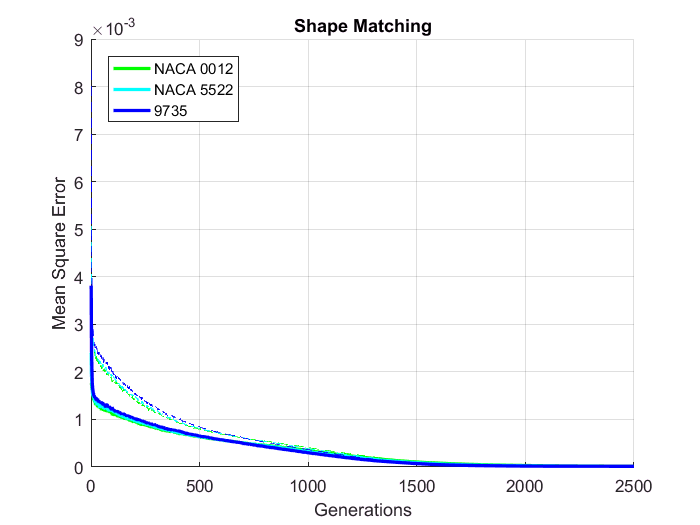

figure(1); clf; hold on;
colorSet = varycolor(4);
for i=1:3
    lineHandles(i) = plot(p(i).meanBestFitness,'-','LineWidth',2,'Color',colorSet(i,:));
    plot(p(i).meanMeanFitness,'--','Color',get(lineHandles(i),'Color'));
end
legend(lineHandles,name,'Location','NorthWest')
xlabel('Generations');ylabel('Mean Square Error');grid on;
%set(gca,'XLim',[0 2500]); 
title('Error over generations')

## Visualization of Resulting Shapes

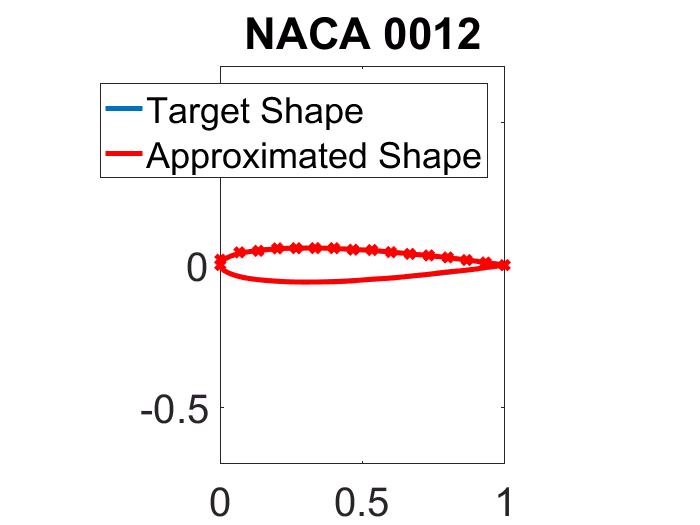

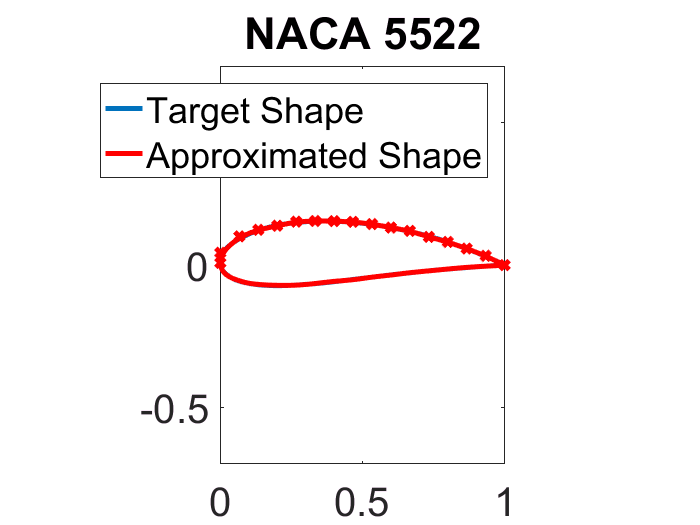

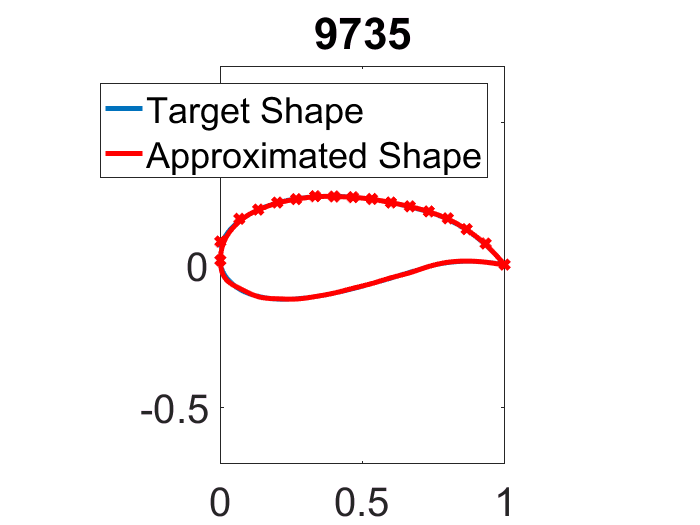

nEvaluationPoints = 256; 

for i=1:3
    nacaNumber = p(i).nacaNumber;
    nacafoil= create_naca(nacaNumber,nEvaluationPoints);
    figure(i+1);
    [foil, nurbs] = pts2ind(p(i).bestSolution,nEvaluationPoints);
    plot(nacafoil(1,:),nacafoil(2,:), 'LineWidth', 3);
    hold on;
    plot(foil(1,:),foil(2,:), 'r', 'LineWidth', 3);
    plot(nurbs.coefs(1,1:end/2),nurbs.coefs(2,1:end/2),'rx', 'LineWidth', 3);
    axis equal;
    axis([0 1 -0.7 0.7]);
    legend('Target Shape', 'Approximated Shape');
    ax = gca;
    ax.FontSize = 24;
    drawnow;
    title(name{i});
    hold off;
end

## Results

As can be seen all three shapes are matched eventually. After about 1800 generations no visual difference between mean and best error can be seen in the figure and after about 2000 generations there is no more visual improvement. Maybe the chosen stopping criterium could be a little higher or the resolution in this part is too low to make out any improvement which is still there.